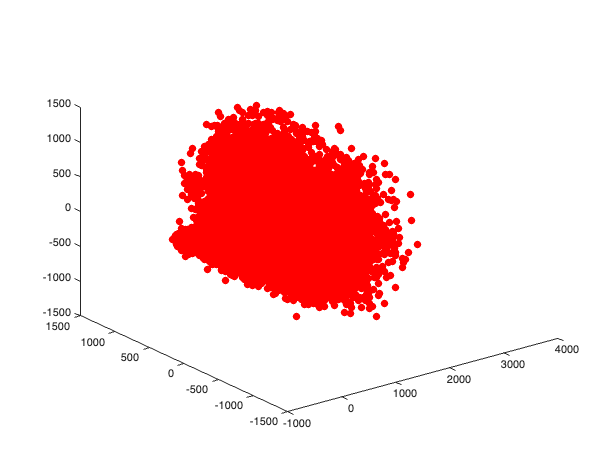

clear all
clc
warning("off")
load ('mnist.mat')
colormap(gray(256))
images = rescale(test.images(:,:,:),0,255);
data = reshape(images,784,10000);


inputs = data';

[coeff,~,~,~,explained,~] = pca(inputs);
Z=inputs*coeff(:,1:3);

figure;
%plot(Z(:,1),Z(:,2),'r.','MarkerSize',10)
view(3);
plot3(Z(:,1),Z(:,2),Z(:,3),'r.','MarkerSize',20)

% generate synaptic weights
SetRNG(111);
n_src = 784;
n_dst = 500;
n_per_src = 20;
synaptic_weights_mat = randn(n_src,n_dst);
[srcIdx,dstIdx] = ConnectHypergeometric(n_dst, n_src, n_per_src);
index = [srcIdx;dstIdx];
for i = 1:n_dst;
    nonzero_idx = index(2,find(index(1,:) == i));
    zero_idx = setdiff(1:n_src,nonzero_idx);
    synaptic_weights_mat(zero_idx,i) = 0;
end
cells = synaptic_weights_mat; %original

% cycle 1, find the cluster winners
ori_cycle1_cells = cells;
cycle1_cells = normc(cells);
cycle1_cells_iter = normc(cells);

% for k = 1:10;
%     cycle1_winners = [];
%     sampled_data = data(:, randperm(size(data, 2)));
%     winner_len_mat = [];
%     winner_average = zeros(784,1,8000);
%     for col = 1:size(sampled_data,2); % loop over all inputs
%         lr = 0.001;
%         input1 = sampled_data(:,col);% each input
%         len_input = norm(input1);
%         input1 = normc(input1);
%         winner_per_cycle = [];
%         product = input1'*cycle1_cells; % the dot products of the input and all cells
%         winning_value = max(product); % max dot product value
%         winning_idx = find(product == winning_value); % index(indices) of winning cell(s)
%         winning_cell = cycle1_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
%         % loop over each winning cell in the set, in case of tied winners,
%         % which may not happen
%         updated_winningset = []; % in case of tied winners
%         for cell_idx = winning_idx;
%             winner = cycle1_cells_iter(:,cell_idx);
%             update_winner_ori = winner+(input1-winner)*lr;
%             winner_average(:,:,cell_idx) = update_winner_ori + winner_average(:,:,cell_idx);
% 
%             len_update_winner = norm(update_winner_ori);
%             update_winner = update_winner_ori/len_update_winner;
%             updated_winningset = [updated_winningset;update_winner];
%             winner_len_mat = [winner_len_mat;[cell_idx,len_input]];           
%             cycle1_cells(:,cell_idx) = update_winner;
%             cycle1_cells_iter(:,cell_idx) = update_winner_ori; 
%             %ori_cycle1_cells(:,cell_idx) = update_winner*len_input;
%         end
%         cycle1_winners = [cycle1_winners;winning_idx];
%     end
% end
% 
% [~,~,ix] = unique(cycle1_winners,"stable");
% winner_stats = [unique(cycle1_winners,"stable"),accumarray(ix,1)];
% 
% for i = 1:size(winner_stats,1);
% winner_average(:,:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1))./winner_stats(i,2);
% cycle1_cells(:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1)); 
% end
% 
% 
% cycle1_winner=cycle1_winners;
% cycle1_winners = unique(cycle1_winners,"stable");
% [~,idx] = max(normr(inputs)*cycle1_cells(:,cycle1_winners),[],2);
% cycle1_winners = cycle1_winners(unique(idx,"stable"));
% cycle1_winners
% 
% for c = cycle1_winners';
%     each_input = winner_len_mat(winner_len_mat(:,1)== c,2);
%     ori_cycle1_cells(:,c) = cycle1_cells(:,c)*mean(each_input);
% end
% cycle1_winner_demask = ori_cycle1_cells(:,cycle1_winners);
% 
% 
% % after cycle 1 plots
% final_all_data = [inputs;cells(:,cycle1_winners)'];
% [coeff,~,~,~,explained,~] = pca(final_all_data);
% Za1=final_all_data*coeff(:,1:3);
% subplot(2,2,2)
% hold on
% view(3)
% plot3(Za1(1:length(data),1),Za1(1:length(data),2),Za1(1:length(data),3),'r.','MarkerSize',10)
% plot3(Za1(end,1),Za1(end,2),Za1(end,3),'bp','MarkerFaceColor','blue','MarkerSize',50)
% title("b) after cycle one")
% legend('input','cycle one winners','Location','NW')
% grid on
% hold off

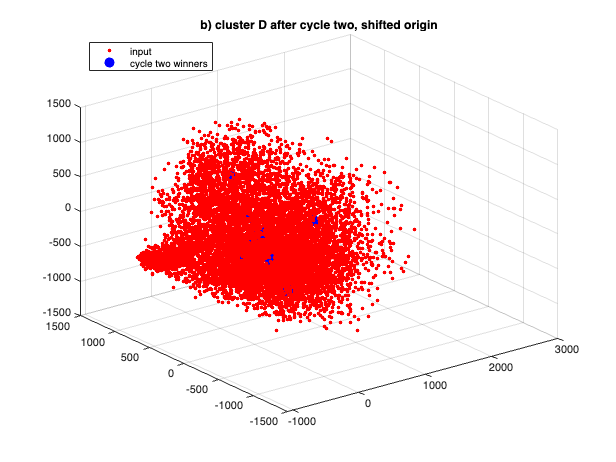

%cycle 2, find the sub-cluster winners
% determine the clutser
ori_cycle2_cells = ori_cycle1_cells;
cycle2_cells = cycle1_cells;
cycle2_cells_iter = cycle1_cells;
%ori_cycle2_cells(:,cycle1_winners) = 0;
%cycle2_cells(:,cycle1_winners) = 0;
%cycle2_cells_iter(:,cycle1_winners) = 0;

cycle2_cells_copy = cycle2_cells;
cycle2_winner_mat = [];
this_winner_mat = [];


lr = 0.001;
%this_idx = c;
sampled_data_fix = data; %select each cluster data
%this_winner = ori_cycle1_cells(:,cycle1_winners(1)); % the cell that "this" cluster wins in cycle 1
this_winner = mean(inputs)';
this_winner_mat = [this_winner_mat;this_winner';this_winner'];

%pull all inputs of this clutser to its center
sampled_data_fix = sampled_data_fix-this_winner;
assign_id = test.labels;

for k = 1:60; % each cluster learns 60 rounds
    winner_len_mat = [];
    cycle2_winners = [];
    sampled_data = sampled_data_fix(:, randperm(size(sampled_data_fix, 2)));
    winner_average = zeros(784,1,n_dst);
    for col = 1:size(sampled_data,2); % loop over all inputs
        input1 = sampled_data(:,col);
        len_input = norm(input1);
        input1 = normc(input1);
        product = input1'*cycle2_cells; % the  dot products of the input and all cells
        winning_value = max(product); % max dot product value
        winning_idx = find(product == winning_value);
        winning_cell = cycle2_cells_iter(:,winning_idx);
        cycle2_winners = [cycle2_winners;winning_idx];
        winner_len_mat = [winner_len_mat;[winning_idx,len_input]];
        update_winner = winning_cell+(input1-winning_cell)*lr;
        winner_average(:,:,winning_idx) = update_winner + winner_average(:,:,winning_idx);
        cycle2_cells_iter(:,winning_idx) = update_winner;  
        update_winner = normc(update_winner);
        cycle2_cells(:,winning_idx) = update_winner;
    end

end

[~,~,ix] = unique(cycle2_winners,"stable");
winner_stats = [unique(cycle2_winners,"stable"),accumarray(ix,1)];
for i = 1:size(winner_stats,1);
winner_average(:,:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1))./winner_stats(i,2);
cycle2_cells_iter(:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1)); 
end

cycle2_winners = unique(cycle2_winners);
for c = cycle2_winners';
    each_input = winner_len_mat(winner_len_mat(:,1)== c,2);
    ori_cycle2_cells(:,c) = cycle2_cells_iter(:,c)*mean(each_input);
end



final_all_data = [sampled_data';ori_cycle2_cells(:,cycle2_winners)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Za2=final_all_data*coeff(:,1:3);
explained = round(explained);

figure;
hold on
view(3)
plot3(Za2(1:10000,1),Za2(1:10000,2),Za2(1:10000,3),'r.','MarkerSize',10)
plot3(Za2(10001:end,1),Za2(10001:end,2),Za2(10001:end,3),'b.','MarkerSize',30)
title("b) cluster D after cycle two, shifted origin")
legend('input','cycle two winners','Location','NW')
grid on
hold off

[~,idx] = max(normc(sampled_data_fix)'*cycle2_cells(:,cycle2_winners),[],2);

[GC,GR] = groupcounts(idx); % stats of all categories
cluster_distribution = [GR,GC];
T = array2table(cluster_distribution)

T = 24×2 table
    cluster_distribution1    cluster_distribution2
    _____________________    _____________________

              1                      1007         
              2                         1         
              3                         1         
              4                       626         
              5                      1202         
              6                         1         
              7                         1         
              8                       769         
              9                         1         
             10                         2         
             11                      1274         
             12                       824         
             13                       629         
             14                       791         
             15                         5         
             16                         1        

cluster_distribution = cluster_distribution(find(cluster_distribution(:,2)>=10),:);
cluster_distribution = [cluster_distribution(:,1),cluster_distribution(:,2)];
T2 = array2table(cluster_distribution)

T2 = 11×2 table
    cluster_distribution1    cluster_distribution2
    _____________________    _____________________

              1                      1007         
              4                       626         
              5                      1202         
              8                       769         
             11                      1274         
             12                       824         
             13                       629         
             14                       791         
             17                      1058         
             19                       936         
             24                       865         


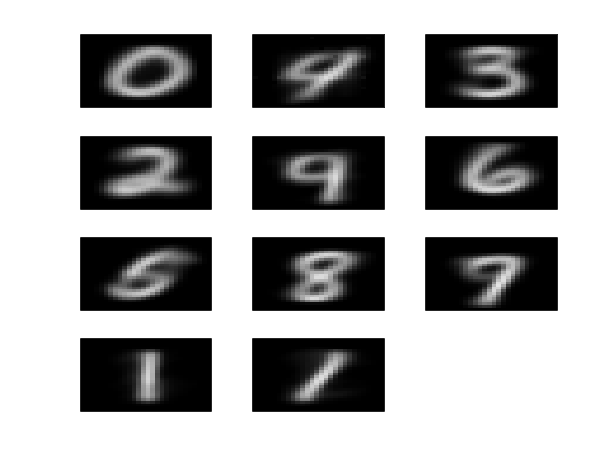


figure;
for i = 1:length(cluster_distribution);%length(id); 
subplot(4,3,i)
k = cluster_distribution(i,1);
colormap(gray(256))
images = ori_cycle2_cells(:,cycle2_winners(k))+this_winner;
%images(images<0) = 0;
image(reshape(images,28,28))
set(gca,'XTick',[], 'YTick', [])
%pause(0.2);
end


figure;
k = 1;
id = find(idx == k);
[GC,GR] = groupcounts(test.labels(id)); %stats of this category 
T3 = array2table([GC,GR])

T3 = 9×2 table
    Var1    Var2
    ____    ____

    836      0  
     34      2  
     14      3  
      5      4  
     34      5  
     42      6  
      8      7  
     16      8  
     18      9  


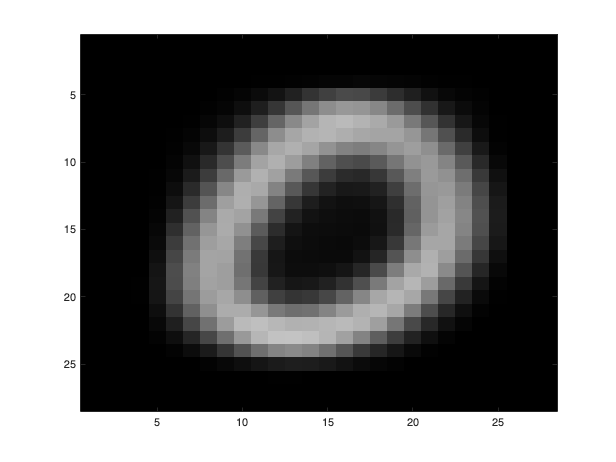

colormap(gray(256))
image(reshape(ori_cycle2_cells(:,cycle2_winners(k))+this_winner,28,28)) %center of this category

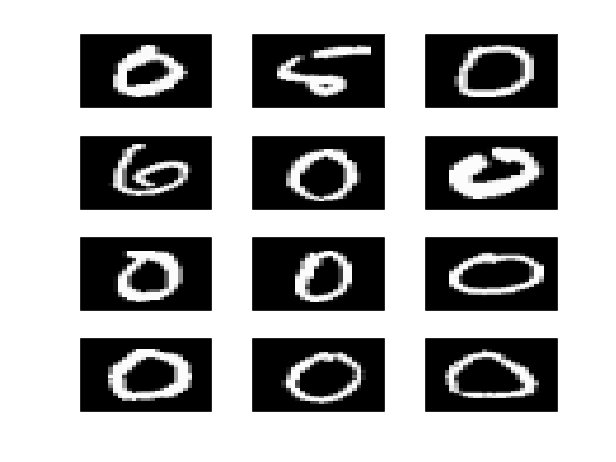


figure;
for i = 1:12;%length(id);
subplot(4,3,i)
colormap(gray(256))
image(reshape(data(:,id(i)),28,28))
set(gca,'XTick',[], 'YTick', [])
%pause(0.2);
end

% for index
[~,idx] = max(normc(sampled_data_fix)'*cycle2_cells(:,cycle2_winners),[],2);
[GC,GR] = groupcounts(idx); 
delete_idx = find(ismember(idx,find(GC<10)));
X = data;
X(:,delete_idx) = [];
assign_id = test.labels;
assign_id(delete_idx) = [];
clustAssignments = idx;
clustAssignments(delete_idx) = [];
cluster_label = [clustAssignments,assign_id];

unique_cluster = unique(clustAssignments);
subdivi_winner_idx = [];
for i = 1:length(unique_cluster)
    assigned = unique_cluster(i);
    labels = cluster_label(find(cluster_label(:,1) == assigned),2);
    num_max_class = numel(find(labels==mode(labels)));

    if length(unique(labels)) == 1 | num_max_class/length(labels) >= 0.7;
        disp('cluster with winner index '+string(assigned)+' is not subdivisible')
    else
        disp('cluster with winner index '+string(assigned)+' is subdivisible')
        subdivi_winner_idx = [subdivi_winner_idx;assigned];
    end
end

cluster with winner index 1 is not subdivisible


cluster with winner index 4 is subdivisible
cluster with winner index 5 is subdivisible


cluster with winner index 8 is not subdivisible


cluster with winner index 11 is subdivisible


cluster with winner index 12 is not subdivisible


cluster with winner index 13 is subdivisible


cluster with winner index 14 is not subdivisible


cluster with winner index 17 is subdivisible
cluster with winner index 19 is subdivisible
cluster with winner index 24 is subdivisible



% k = 16;
% id = find(idx == k);
% [GC,GR] = groupcounts(test.labels(id)); %stats of this category 
% T3 = array2table([GC,GR], 'VariableNames', {'counts', 'digits'})
% colormap(gray(256))
% image(reshape(ori_cycle2_cells(:,cycle2_winners(k))+this_winner,28,28))
% 
% k = 0;
% for i = 101:136;%length(id); 
% k = k+1;
% subplot(6,6,k)
% colormap(gray(256))
% image(reshape(data(:,id(i)),28,28))
% %pause(0.2);
% end

winner_id = cycle2_winners(clustAssignments);
PTY = purity(clustAssignments,assign_id)

PTY = 0.6409

NMI = nmi(assign_id, clustAssignments)

NMI = 0.5228

[RI, ARI] = randindex(assign_id, clustAssignments)

RI = 0.8972

ARI = 0.4175

[s] = ClusterEvalSilhouette (X', clustAssignments, 'cosine')

s = 0.1416

ch = ClusterEvalCalinskiHarabasz(X', clustAssignments)

ch = 369.7483

[db] = ClusterEvalDaviesBouldin (X', clustAssignments)

db = 2.7565



K_means_assign = kmeans(X',11);
PTY = purity(K_means_assign,assign_id)

PTY = 0.6448

NMI = nmi(assign_id, K_means_assign)

NMI = 0.5249

[RI, ARI] = randindex(assign_id, K_means_assign)

RI = 0.8955

ARI = 0.4230

[s] = ClusterEvalSilhouette (X', K_means_assign, 'cosine')

s = 0.1243

ch = ClusterEvalCalinskiHarabasz(X', K_means_assign)

ch = 368.4537

[db] = ClusterEvalDaviesBouldin (X', K_means_assign)

db = 2.8937